dane = audioDatastore("dane\","IncludeSubfolders", true, 'LabelSource','foldernames')

dane =   audioDatastore with properties:

                       Files: {
                              ' ...\MATLAB\Projects\BayesMusicClassification\dane\blues\blues.00000.wav';
                              ' ...\MATLAB\Projects\BayesMusicClassification\dane\blues\blues.00001.wav';
                              ' ...\MATLAB\Projects\BayesMusicClassification\dane\blues\blues.00002.wav'
                               ... and 1401 more
                              }
                     Folders: {
                              'C:\Users\ja\MATLAB\Projects\BayesMusicClassification\dane'
                              }
                      Labels: [blues; blues; blues ... and 1401 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


[daneTrain, daneTest] = splitEachLabel(dane,0.8);
[x,xinfo] = read(daneTrain);
xinfo

xinfo = struct with fields:
    SampleRate: 22050
      FileName: 'C:\Users\ja\MATLAB\Projects\BayesMusicClassification\dane\blues\blues.00000.wav'
         Label: blues


%sound(x,xinfo.SampleRate)


%%

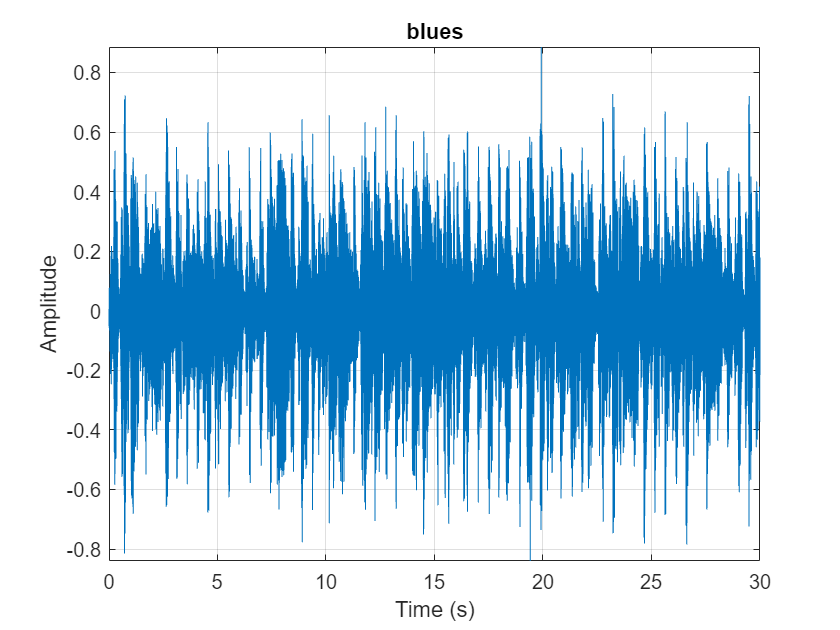


t = (0:numel(x)-1)/xinfo.SampleRate;
figure
plot(t,x)
title(xinfo.Label)
grid on
axis tight
ylabel("Amplitude")
xlabel("Time (s)")

% Create and set up an audioFeatureExtractor object
extractor = audioFeatureExtractor("SampleRate",xinfo.SampleRate, ...
    "linearSpectrum",true,"melSpectrum",true, ...
    "mfcc",true,"mfccDelta",true, ...
    "mfccDeltaDelta",true,"spectralCentroid",true, ...
    "spectralCrest",true,"spectralFlatness",true, ...
    "spectralFlux",true,"spectralSkewness",true, ...
    "spectralSlope",true,"pitch",true, ...
    "harmonicRatio",true,"zerocrossrate",true, ...
    "shortTimeEnergy",true);


featureMatrix = extract(extractor,x);
[numWindows,numFeatures] = size(featureMatrix)

numWindows = 1291

numFeatures = 594

%features = extract(extractor,x)
%plot(features)


daneTrainT = transform(daneTrain,@(x){extract(extractor,x)})

daneTrainT =   TransformedDatastore with properties:

      UnderlyingDatastores: {audioDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
                Transforms: {@(x){extract(extractor,x)}}
               IncludeInfo: 0


features = readall(daneTrainT)

features = 1123×1 cell array
    {1291×594 double}
    {1291×594 double}
    {1291×594 double}
    {1291×594 double}
    {1291×594 double}
    {1291×594 double}
    {1291×594 double}
    {1291×594 double}
    {1291×594 double}
    {1291×594 double}
    {1291×594 double}
    {1291×594 double}
    {1291×594 double}
    {1291×594 double}
    {1291×594 double}
    {1291×594 double}


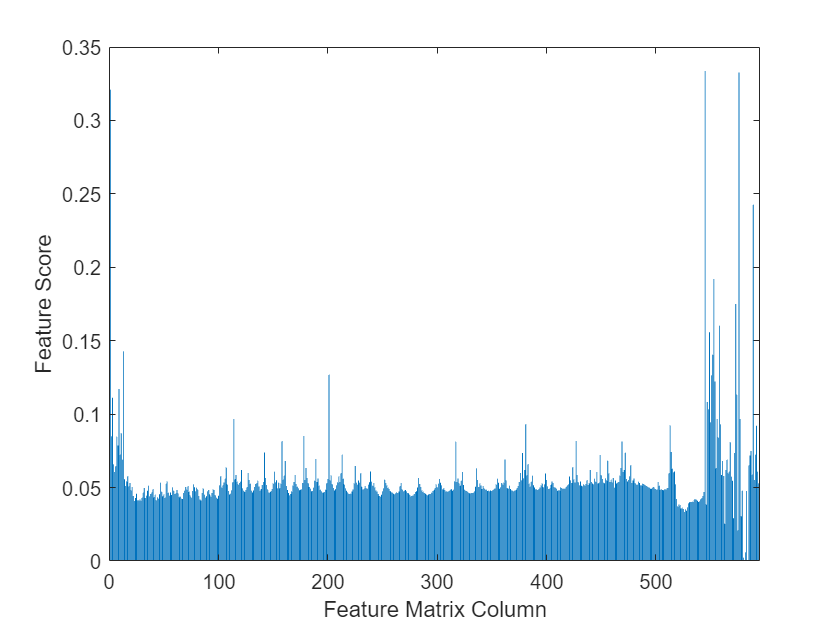


N = cellfun(@(x)size(x,1),features);
T = repelem(daneTrain.Labels,N);
X = cat(1,features{:});
rng("default") % for reproducibility
[featureSelectionIdx,featureSelectionScores] = fscmrmr(X,T);
figure
bar(featureSelectionScores)
ylabel("Feature Score")
xlabel("Feature Matrix Column")

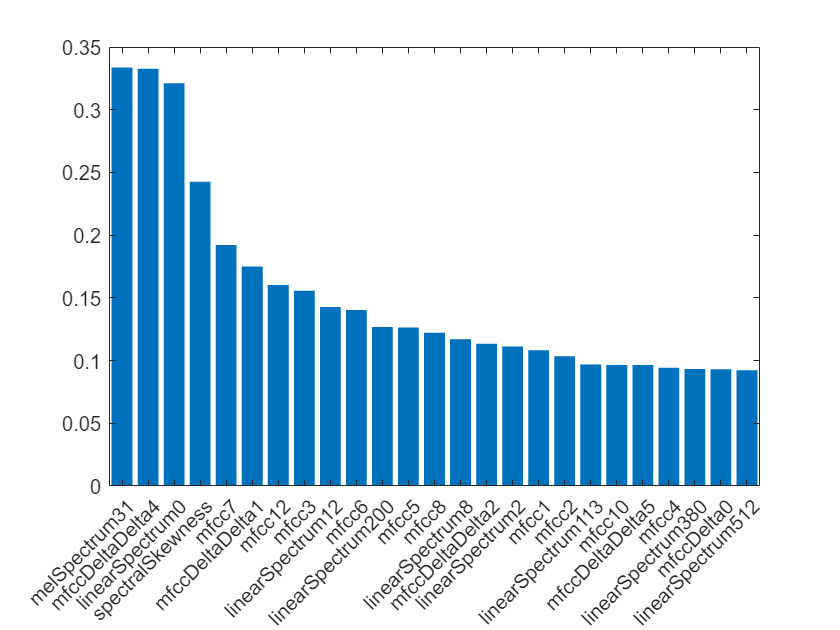

outputMap = info(extractor);
featurenames = uniqueFeatureName(outputMap);

featurenamesSorted = featurenames(featureSelectionIdx);
figure
bar(reordercats(categorical(featurenames),featurenamesSorted),featureSelectionScores)
xlim([featurenamesSorted(1),featurenamesSorted(25)])

selectedFeatureIndex = featureSelectionIdx(1:30);
Mdl = fitcnb(X(:,selectedFeatureIndex),T)

Mdl =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [blues    classical    country    disco    hiphop    jazz    metal    pop    reggae    rock]
            ScoreTransform: 'none'
           NumObservations: 1450587
         DistributionNames: {1×30 cell}
    DistributionParameters: {10×30 cell}


  Properties, Methods


[x,xInfo] = read(adsTest);
sound(x,xInfo.SampleRate)

t = (0:numel(x)-1)/xInfo.SampleRate;
figure
plot(t,x)
title("Label: " + xInfo.Label)
grid on
axis tight
ylabel("Amplitude")
xlabel("Time (s)")